clc
clear
clf

## Settings

read_data = true;
load_models = true;
train_LDA = true;
make_LDA_pred = false;
train_LDA_sep = false;
make_LDA_pred_sep = false;
save_models = false;
drift_pred = true;
save_predictions = false;
save_predictions_sep = false;
load_predictions = true;
load_predictions_sep = true;
plot_conf = false;
plot_conf_sep = false;
new_predict = true;
adj_predict = true;
plot_performance = false;
plot_adj_confchart = false;
calc_sep_performance = false;
calc_drift_performance = true;
plot_ROC_curves_sep = true;
save_performance = false;

## Read data

if (read_data)
% Full testing set
FullSet = readtable("results\Data\testing_measured_data_combined.csv");

A.features = [FullSet.c_LO_measured FullSet.c_RE_measured FullSet.f_PLSP_measured...
                FullSet.f_PLSS_measured FullSet.f_LO_measured FullSet.f_LE_measured... 
                FullSet.c_PLS_measured FullSet.c_LE_measured FullSet.c_RaffP_measured...
                FullSet.c_RaffS_measured FullSet.c_BO_measured]

X = A.features;
y = FullSet.state_code;
y_s = string(y);

% Training set
TrainingSet = readtable("results\Data\training_measured_data_combined.csv");

B.features = [TrainingSet.c_LO_measured TrainingSet.c_RE_measured TrainingSet.f_PLSP_measured...
                TrainingSet.f_PLSS_measured TrainingSet.f_LO_measured TrainingSet.f_LE_measured... 
                TrainingSet.c_PLS_measured TrainingSet.c_LE_measured TrainingSet.c_RaffP_measured...
                TrainingSet.c_RaffS_measured TrainingSet.c_BO_measured]

% Testing set - only single faults
SeparateSet = readtable("results\Data\testing_separate_measured_data_combined.csv");

C.features = [SeparateSet.c_LO_measured SeparateSet.c_RE_measured SeparateSet.f_PLSP_measured...
                SeparateSet.f_PLSS_measured SeparateSet.f_LO_measured SeparateSet.f_LE_measured... 
                SeparateSet.c_PLS_measured SeparateSet.c_LE_measured SeparateSet.c_RaffP_measured...
                SeparateSet.c_RaffS_measured SeparateSet.c_BO_measured]
C.y = SeparateSet.state_code;

drift_data = readtable("results\Data\testing_measured_data_drift.csv");

D.features = [drift_data.c_LO_measured drift_data.c_RE_measured drift_data.f_PLSP_measured...
                drift_data.f_PLSS_measured drift_data.f_LO_measured drift_data.f_LE_measured... 
                drift_data.c_PLS_measured drift_data.c_LE_measured drift_data.c_RaffP_measured...
                drift_data.c_RaffS_measured drift_data.c_BO_measured]
D.y = drift_data.state_code;

end

A = struct with fields:
    features: [2073608×11 double]


B = struct with fields:
    features: [1296005×11 double]


C = struct with fields:
    features: [1296005×11 double]


D = struct with fields:
    features: [1296005×11 double]


y_C = C.y;
y_D = D.y;

## Load models

if (load_models)
load('results\Models\gaussian_SVM_model.mat');

load('results\Models\kNN_2comp_model.mat');

load('results\Models\kNN_4comp_model.mat');

load('results\Models\kNN_model.mat');
kNN_model = final_kNN_model;

load('results\Models\LDA_2comp_model.mat');

load('results\Models\LDA_4comp_model.mat');
end

## Make predictions

X_N = normalize(X);
B_N = normalize(B.features);
C_N = normalize(C.features);
D_N = normalize(D.features);
y_B = TrainingSet.state_code;

if (train_LDA)
% Apply LDA for dimensionality reduction 2 components
LDA2.num_components = 2;
lda_model = fitcdiscr(B_N, y_B); % Fit the LDA model
[LDA2.eigenvectors, LDA2.eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, LDA2.sorted_indices] = sort(diag(LDA2.eigenvalues), 'descend');
LDA2.projection_matrix = LDA2.eigenvectors(:, LDA2.sorted_indices(1:LDA2.num_components));

% Project training and testing data onto the LDA components
LDA2.B_reduced = B_N * LDA2.projection_matrix;
LDA2.X_reduced = X_N * LDA2.projection_matrix;
kNN_2comp_model = fitcknn(LDA2.B_reduced, y_B, 'NumNeighbors', 90);
LDA_2comp_model = fitcdiscr(LDA2.B_reduced, y_B);

% Apply LDA for dimensionality reduction 2 components
LDA4.num_components = 4;
[LDA4.eigenvectors, LDA4.eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, LDA4.sorted_indices] = sort(diag(LDA4.eigenvalues), 'descend');
LDA4.projection_matrix = LDA4.eigenvectors(:, LDA4.sorted_indices(1:LDA4.num_components));

% Project training and testing data onto the LDA components
LDA4.B_reduced = B_N * LDA4.projection_matrix;
LDA4.X_reduced = X_N * LDA4.projection_matrix;
kNN_4comp_model = fitcknn(LDA4.B_reduced, y_B, 'NumNeighbors', 9);
LDA_4comp_model = fitcdiscr(LDA4.B_reduced, y_B);
end

% Train LDA separate
if(train_LDA_sep)
    LDA2.C_reduced = C_N * LDA2.projection_matrix;
    LDA4.C_reduced = C_N * LDA4.projection_matrix;
end

if (save_models)
    save('results/Models/kNN_2comp_model.mat', 'kNN_2comp_model');
    save('results/Models/kNN_4comp_model.mat', 'kNN_4comp_model');
    save('results/Models/LDA_2comp_model.mat', 'LDA_2comp_model');
    save('results/Models/LDA_4comp_model.mat', 'LDA_4comp_model');
end

if (make_LDA_pred)
    [LDA2.y_pred, LDA2.scores, LDA2.cost] = predict(LDA_2comp_model, LDA2.X_reduced);
    
    [LDA4.y_pred, LDA4.scores, LDA4.cost] = predict(LDA_4comp_model, LDA4.X_reduced);
    
    [kNN2.y_pred, kNN2.scores, kNN2.cost] = predict(kNN_2comp_model, LDA2.X_reduced);
    
    [kNN4.y_pred, kNN4.scores, kNN4.cost] = predict(kNN_4comp_model, LDA4.X_reduced);
    % kNN Only
    [kNN.y_pred, kNN.scores, kNN.cost] = predict(kNN_model, X);
    
    % Gaussian SVM
    [SVM_G.y_pred, SVM_G.scores] = gaussian_SVM_model.predictFcn(X);
end

if (make_LDA_pred_sep)
    [LDA2_sep.y_pred, LDA2_sep.scores, LDA2_sep.cost] = predict(LDA_2comp_model, LDA2.C_reduced);
    
    [LDA4_sep.y_pred, LDA4_sep.scores, LDA4_sep.cost] = predict(LDA_4comp_model, LDA4.C_reduced);
    
    [kNN2_sep.y_pred, kNN2_sep.scores, kNN2_sep.cost] = predict(kNN_2comp_model, LDA2.C_reduced);
    
    [kNN4_sep.y_pred, kNN4_sep.scores, kNN4_sep.cost] = predict(kNN_4comp_model, LDA4.C_reduced);
    % kNN_sep Only
    [kNN_sep.y_pred, kNN_sep.scores, kNN_sep.cost] = predict(kNN_model, C.features);
    
    % Gaussian SVM
    [SVM_G_sep.y_pred, SVM_G_sep.scores] = gaussian_SVM_model.predictFcn(C.features);
end

if (drift_pred)
    LDA2.D_reduced = D_N * LDA2.projection_matrix;
    LDA4.D_reduced = D_N * LDA4.projection_matrix;
    
    [LDA2_drift.y_pred, LDA2_drift.scores, LDA2_drift.cost] = predict(LDA_2comp_model, LDA2.D_reduced);
    
    [LDA4_drift.y_pred, LDA4_drift.scores, LDA4_drift.cost] = predict(LDA_4comp_model, LDA4.D_reduced);
    
    [kNN2_drift.y_pred, kNN2_drift.scores, kNN2_drift.cost] = predict(kNN_2comp_model, LDA2.D_reduced);
    
    [kNN4_drift.y_pred, kNN4_drift.scores, kNN4_drift.cost] = predict(kNN_4comp_model, LDA4.D_reduced);
    % kNN_drift Only
    [kNN_drift.y_pred, kNN_drift.scores, kNN_drift.cost] = predict(kNN_model, D.features);
    
    % Gaussian SVM
    [SVM_G_drift.y_pred, SVM_G_drift.scores] = gaussian_SVM_model.predictFcn(D.features);
end

if (save_predictions)
    save('results/Predictions/kNN.mat', 'kNN');
    save('results/Predictions/kNN2.mat', 'kNN2');
    save('results/Predictions/kNN4.mat', 'kNN4');
    save('results/Predictions/LDA2.mat', 'LDA2');
    save('results/Predictions/LDA4.mat', 'LDA4');
    save('results/Predictions/SVM_G.mat', 'SVM_G');
end

if (save_predictions_sep)
    save('results/Predictions/kNN_sep.mat', 'kNN_sep');
    save('results/Predictions/kNN2_sep.mat', 'kNN2_sep');
    save('results/Predictions/kNN4_sep.mat', 'kNN4_sep');
    save('results/Predictions/LDA2_sep.mat', 'LDA2_sep');
    save('results/Predictions/LDA4_sep.mat', 'LDA4_sep');
    save('results/Predictions/SVM_G_sep.mat', 'SVM_G_sep');
end

if (load_predictions)
    load('results\Predictions\kNN.mat');
    load('results\Predictions\kNN2.mat');
    load('results\Predictions\kNN4.mat');
    load('results\Predictions\LDA2.mat');
    load('results\Predictions\LDA4.mat');
    load('results\Predictions\SVM_G.mat');
end

if (load_predictions_sep)
    load('results\Predictions\kNN_sep.mat');
    load('results\Predictions\kNN2_sep.mat');
    load('results\Predictions\kNN4_sep.mat');
    load('results\Predictions\LDA2_sep.mat');
    load('results\Predictions\LDA4_sep.mat');
    load('results\Predictions\SVM_G_sep.mat');
end

if (plot_conf)
LDA2.mat = confusionmat(y, LDA2.y_pred);
disp('LDA 2 Comp Confusion Matrix:');
disp(LDA2.mat);
confusionchart(y, LDA2.y_pred)
title('LDA 2 comp Confusion Chart - Before adjusting predictions');
print('results/Performance/testing/Pre_adj/LDA2_confchart', '-dpng', '-r600')

LDA4.mat = confusionmat(y, LDA4.y_pred);
disp('LDA 4 Comp Confusion Matrix:');
disp(LDA4.mat);
confusionchart(y, LDA4.y_pred)
title('LDA 4 comp Confusion Chart - Before adjusting predictions');
print('results/Performance/testing/Pre_adj/LDA4_confchart', '-dpng', '-r600')

kNN2.mat = confusionmat(y, kNN2.y_pred);
disp('kNN 2 Comp Confusion Matrix:');
disp(kNN2.mat);
confusionchart(y, kNN2.y_pred)
title('k-Nearest Neighbours 2 comp Confusion Chart - Before adjusting predictions');
print('results/Performance/testing/Pre_adj/kNN2_confchart', '-dpng', '-r600')

kNN4.mat = confusionmat(y, kNN4.y_pred);
disp('kNN 4 Comp Confusion Matrix:');
disp(kNN4.mat);
confusionchart(y, kNN4.y_pred)
title('k-Nearest Neighbours 4 comp Confusion Chart - Before adjusting predictions');
print('results/Performance/testing/Pre_adj/kNN4_confchart', '-dpng', '-r600')

kNN.mat = confusionmat(y, kNN.y_pred);
disp('kNN Confusion Matrix:');
disp(kNN.mat);
confusionchart(y, kNN.y_pred)
title('k-Nearest Neighbours Confusion Chart - Before adjusting predictions');
print('results/Performance/testing/Pre_adj/kNN_confchart', '-dpng', '-r600')

SVM_G.mat = confusionmat(y, SVM_G.y_pred);
disp('SVM Gaussian Confusion Matrix:');
disp(SVM_G.mat);
confusionchart(y, SVM_G.y_pred)
title('SVM Gaussian Confusion Chart - Before adjusting predictions');
print('results/Performance/testing/Pre_adj/SVM_G_confchart', '-dpng', '-r600')
end

if (plot_conf_sep)
LDA2_sep.mat = confusionmat(y_C, LDA2_sep.y_pred);
disp('LDA 2 Comp Confusion Matrix:');
disp(LDA2_sep.mat);
confusionchart(y_C, LDA2_sep.y_pred)
title('LDA 2 comp Confusion Chart - Separate faults');
print('results/Performance/testing_half/LDA2_confchart', '-dpng', '-r600')

LDA4_sep.mat = confusionmat(y_C, LDA4_sep.y_pred);
disp('LDA 4 Comp Confusion Matrix:');
disp(LDA4_sep.mat);
confusionchart(y_C, LDA4_sep.y_pred)
title('LDA 4 comp Confusion Chart - Separate faults');
print('results/Performance/testing_half/LDA4_confchart', '-dpng', '-r600')

kNN2_sep.mat = confusionmat(y_C, kNN2_sep.y_pred);
disp('kNN 2 Comp Confusion Matrix:');
disp(kNN2_sep.mat);
confusionchart(y_C, kNN2_sep.y_pred)
title('k-Nearest Neighbours 2 comp Confusion Chart - Separate faults');
print('results/Performance/testing_half/kNN2_confchart', '-dpng', '-r600')

kNN4_sep.mat = confusionmat(y_C, kNN4_sep.y_pred);
disp('kNN 4 Comp Confusion Matrix:');
disp(kNN4_sep.mat);
confusionchart(y_C, kNN4_sep.y_pred)
title('k-Nearest Neighbours 4 comp Confusion Chart - Separate faults');
print('results/Performance/testing_half/kNN4_confchart', '-dpng', '-r600')

kNN_sep.mat = confusionmat(y_C, kNN_sep.y_pred);
disp('kNN Confusion Matrix:');
disp(kNN_sep.mat);
confusionchart(y_C, kNN_sep.y_pred)
title('k-Nearest Neighbours Confusion Chart - Separate faults');
print('results/Performance/testing_half/kNN_confchart', '-dpng', '-r600')

SVM_G_sep.mat = confusionmat(y_C, SVM_G_sep.y_pred);
disp('SVM Gaussian Confusion Matrix:');
disp(SVM_G_sep.mat);
confusionchart(y_C, SVM_G_sep.y_pred)
title('SVM Gaussian Confusion Chart - Separate faults');
print('results/Performance/testing_half/SVM_G_confchart', '-dpng', '-r600')
end

if (new_predict)
    kNN.new_scores = [kNN.scores(:, 1) kNN.scores(:,3:end)];
    kNN2.new_scores = [kNN2.scores(:, 1) kNN2.scores(:,3:end)];
    kNN4.new_scores = [kNN4.scores(:, 1) kNN4.scores(:,3:end)];
    LDA2.new_scores = [LDA2.scores(:, 1) LDA2.scores(:,3:end)];
    LDA4.new_scores = [LDA4.scores(:, 1) LDA4.scores(:,3:end)];
    SVM_G.new_scores = [SVM_G.scores(:,1) SVM_G.scores(:,3:end)];
end


y_adj = y;
y_adj{2} = "Other Fault";
y_adj_s = string(y_adj);

if (adj_predict)
% kNN accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    kNN.new_pred_bin = zeros(size(kNN.new_scores));
    kNN.new_pred_bin(abs(kNN.new_scores) > threshold(i)) = 1;
    sum(kNN.new_pred_bin);
    kNN.new_pred = table();
    kNN.new_pred.pred = kNN.y_pred;
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 1 0 0], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 1 1 1], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 0 1 1], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 0 0 1], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 1 1 1], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 1 0 1], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 1 1], 2)) = "Other Fault";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 1 0 1], 2)) = "Other Fault";
    kNN.combined_pred(:, i) = kNN.new_pred.label;
    kNN.accuracy(i) = sum(strcmpi(y, kNN.combined_pred(:, i))) / length(y); 
    kNN.c = confusionmat(y_adj_s, kNN.combined_pred(:, i));
    kNN.c_correct = diag(kNN.c);
    kNN.c_correct_sq = [zeros(8, 1) diag(kNN.c_correct(2:end))];
    kNN.c_faulty = kNN.c(2:end, :);
    kNN.TP(i) = sum(kNN.c_correct_sq, "all");
    kNN.false = kNN.c - diag(kNN.c_correct);
    kNN.FP(i) = sum(kNN.false(:, 2:end), "all");
    kNN.FN(i) = sum(kNN.c(2:end, 1));
    kNN.TN(i) = kNN.c(1,1);
    kNN.precision(i) = kNN.TP(i)/(kNN.TP(i)+kNN.FP(i));
    kNN.sensitivity(i) = kNN.TP(i)/(kNN.TP(i)+kNN.FN(i));
    kNN.specificity(i) = kNN.TN(i)/(kNN.TN(i)+kNN.FP(i));
    if (ismember(i, [10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]))
        disp(i);
    end
end 

kNN.accuracy = kNN.accuracy';
kNN.FP = kNN.FP';
kNN.TP = kNN.TP';
kNN.FN = kNN.FN';
kNN.TN = kNN.TN';
kNN.precision = kNN.precision';
kNN.sensitivity = kNN.sensitivity';
kNN.specificity = kNN.specificity';
[M_kNN, I_kNN] = max(kNN.accuracy);
best_threshold_kNN = threshold(I_kNN); 
kNN.FPR = kNN.FP./(kNN.FP+kNN.TN);
kNN.TPR = kNN.TP./(kNN.FP+kNN.TN);

% kNN2 accuracy
for i = 1:200
    kNN2.new_pred_bin = zeros(size(kNN2.new_scores));
    kNN2.new_pred_bin(abs(kNN2.new_scores) > threshold(i)) = 1;
    sum(kNN2.new_pred_bin);
    kNN2.new_pred = table();
    kNN2.new_pred.pred = kNN2.y_pred;
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 1 0 0], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 1 1 1], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 0 1 1], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 0 0 1], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 1 1 1], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 1 0 1], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 1 1], 2)) = "Other Fault";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 1 0 1], 2)) = "Other Fault";
    kNN2.combined_pred(:, i) = kNN2.new_pred.label;
    kNN2.accuracy(i) = sum(strcmpi(y, kNN2.combined_pred(:, i))) / length(y); 
    kNN2.c = confusionmat(y_adj_s, kNN2.combined_pred(:, i));
    kNN2.c_correct = diag(kNN2.c);
    kNN2.c_correct_sq = [zeros(8, 1) diag(kNN2.c_correct(2:end))];
    kNN2.c_faulty = kNN2.c(2:end, :);
    kNN2.TP(i) = sum(kNN2.c_correct_sq, "all");
    kNN2.false = kNN2.c - diag(kNN2.c_correct);
    kNN2.FP(i) = sum(kNN2.false(:, 2:end), "all");
    kNN2.FN(i) = sum(kNN2.c(2:end, 1));
    kNN2.TN(i) = kNN2.c(1,1);
    kNN2.precision(i) = kNN2.TP(i)/(kNN2.TP(i)+kNN2.FP(i));
    kNN2.sensitivity(i) = kNN2.TP(i)/(kNN2.TP(i)+kNN2.FN(i));
    kNN2.specificity(i) = kNN2.TN(i)/(kNN2.TN(i)+kNN2.FP(i));
    if (ismember(i, [10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]))
        disp(i);
    end
end 

kNN2.accuracy = kNN2.accuracy';
kNN2.FP = kNN2.FP';
kNN2.TP = kNN2.TP';
kNN2.FN = kNN2.FN';
kNN2.TN = kNN2.TN';
kNN2.precision = kNN2.precision';
kNN2.sensitivity = kNN2.sensitivity';
kNN2.specificity = kNN2.specificity';
[M_kNN2, I_kNN2] = max(kNN2.accuracy);
best_threshold_kNN2 = threshold(I_kNN2); 
kNN2.FPR = kNN2.FP./(kNN2.FP+kNN2.TN);
kNN2.TPR = kNN2.TP./(kNN2.FP+kNN2.TN);

% kNN4 accuracy
for i = 1:200
    kNN4.new_pred_bin = zeros(size(kNN4.new_scores));
    kNN4.new_pred_bin(abs(kNN4.new_scores) > threshold(i)) = 1;
    sum(kNN4.new_pred_bin);
    kNN4.new_pred = table();
    kNN4.new_pred.pred = kNN4.y_pred;
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 1 0 0], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 1 1 1], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 0 1 1], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 0 0 1], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 1 1 1], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 1 0 1], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 1 1], 2)) = "Other Fault";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 1 0 1], 2)) = "Other Fault";
    kNN4.combined_pred(:, i) = kNN4.new_pred.label;
    kNN4.accuracy(i) = sum(strcmpi(y, kNN4.combined_pred(:, i))) / length(y); 
    kNN4.c = confusionmat(y_adj_s, kNN4.combined_pred(:, i));
    kNN4.c_correct = diag(kNN4.c);
    kNN4.c_correct_sq = [zeros(8, 1) diag(kNN4.c_correct(2:end))];
    kNN4.c_faulty = kNN4.c(2:end, :);
    kNN4.TP(i) = sum(kNN4.c_correct_sq, "all");
    kNN4.false = kNN4.c - diag(kNN4.c_correct);
    kNN4.FP(i) = sum(kNN4.false(:, 2:end), "all");
    kNN4.FN(i) = sum(kNN4.c(2:end, 1));
    kNN4.TN(i) = kNN4.c(1,1);
    kNN4.precision(i) = kNN4.TP(i)/(kNN4.TP(i)+kNN4.FP(i));
    kNN4.sensitivity(i) = kNN4.TP(i)/(kNN4.TP(i)+kNN4.FN(i));
    kNN4.specificity(i) = kNN4.TN(i)/(kNN4.TN(i)+kNN4.FP(i));
    if (ismember(i, [10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]))
        disp(i);
    end
end 

kNN4.accuracy = kNN4.accuracy';
kNN4.FP = kNN4.FP';
kNN4.TP = kNN4.TP';
kNN4.FN = kNN4.FN';
kNN4.TN = kNN4.TN';
kNN4.precision = kNN4.precision';
kNN4.sensitivity = kNN4.sensitivity';
kNN4.specificity = kNN4.specificity';
[M_kNN4, I_kNN4] = max(kNN4.accuracy);
best_threshold_kNN4 = threshold(I_kNN4); 
kNN4.FPR = kNN4.FP./(kNN4.FP+kNN4.TN);
kNN4.TPR = kNN4.TP./(kNN4.FP+kNN4.TN);

% LDA2 accuracy
for i = 1:200
    LDA2.new_pred_bin = zeros(size(LDA2.new_scores));
    LDA2.new_pred_bin(abs(LDA2.new_scores) > threshold(i)) = 1;
    sum(LDA2.new_pred_bin);
    LDA2.new_pred = table();
    LDA2.new_pred.pred = LDA2.y_pred;
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 1 0 0], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 1 1 1], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 0 1 1], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 0 0 1], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 1 1 1], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 1 0 1], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 1 1], 2)) = "Other Fault";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 1 0 1], 2)) = "Other Fault";
    LDA2.combined_pred(:, i) = LDA2.new_pred.label;
    LDA2.accuracy(i) = sum(strcmpi(y, LDA2.combined_pred(:, i))) / length(y); 
    LDA2.c = confusionmat(y_adj_s, LDA2.combined_pred(:, i));
    LDA2.c_correct = diag(LDA2.c);
    LDA2.c_correct_sq = [zeros(8, 1) diag(LDA2.c_correct(2:end))];
    LDA2.c_faulty = LDA2.c(2:end, :);
    LDA2.TP(i) = sum(LDA2.c_correct_sq, "all");
    LDA2.false = LDA2.c - diag(LDA2.c_correct);
    LDA2.FP(i) = sum(LDA2.false(:, 2:end), "all");
    LDA2.FN(i) = sum(LDA2.c(2:end, 1));
    LDA2.TN(i) = LDA2.c(1,1);
    LDA2.precision(i) = LDA2.TP(i)/(LDA2.TP(i)+LDA2.FP(i));
    LDA2.sensitivity(i) = LDA2.TP(i)/(LDA2.TP(i)+LDA2.FN(i));
    LDA2.specificity(i) = LDA2.TN(i)/(LDA2.TN(i)+LDA2.FP(i));
    if (ismember(i, [10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]))
        disp(i);
    end
end 

LDA2.accuracy = LDA2.accuracy';
LDA2.FP = LDA2.FP';
LDA2.TP = LDA2.TP';
LDA2.FN = LDA2.FN';
LDA2.TN = LDA2.TN';
LDA2.precision = LDA2.precision';
LDA2.sensitivity = LDA2.sensitivity';
LDA2.specificity = LDA2.specificity';
[M_LDA2, I_LDA2] = max(LDA2.accuracy);
best_threshold_LDA2 = threshold(I_LDA2); 
LDA2.FPR = LDA2.FP./(LDA2.FP+LDA2.TN);
LDA2.TPR = LDA2.TP./(LDA2.FP+LDA2.TN);

% LDA4 accuracy
for i = 1:200
    LDA4.new_pred_bin = zeros(size(LDA4.new_scores));
    LDA4.new_pred_bin(abs(LDA4.new_scores) > threshold(i)) = 1;
    sum(LDA4.new_pred_bin);
    LDA4.new_pred = table();
    LDA4.new_pred.pred = LDA4.y_pred;
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 1 0 0], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 1 1 1], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 0 1 1], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 0 0 1], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 1 1 1], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 1 0 1], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 1 1], 2)) = "Other Fault";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 1 0 1], 2)) = "Other Fault";
    LDA4.combined_pred(:, i) = LDA4.new_pred.label;
    LDA4.accuracy(i) = sum(strcmpi(y, LDA4.combined_pred(:, i))) / length(y); 
    LDA4.c = confusionmat(y_adj_s, LDA4.combined_pred(:, i));
    LDA4.c_correct = diag(LDA4.c);
    LDA4.c_correct_sq = [zeros(8, 1) diag(LDA4.c_correct(2:end))];
    LDA4.c_faulty = LDA4.c(2:end, :);
    LDA4.TP(i) = sum(LDA4.c_correct_sq, "all");
    LDA4.false = LDA4.c - diag(LDA4.c_correct);
    LDA4.FP(i) = sum(LDA4.false(:, 2:end), "all");
    LDA4.FN(i) = sum(LDA4.c(2:end, 1));
    LDA4.TN(i) = LDA4.c(1,1);
    LDA4.precision(i) = LDA4.TP(i)/(LDA4.TP(i)+LDA4.FP(i));
    LDA4.sensitivity(i) = LDA4.TP(i)/(LDA4.TP(i)+LDA4.FN(i));
    LDA4.specificity(i) = LDA4.TN(i)/(LDA4.TN(i)+LDA4.FP(i));
    if (ismember(i, [10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]))
        disp(i);
    end
end 

LDA4.accuracy = LDA4.accuracy';
LDA4.FP = LDA4.FP';
LDA4.TP = LDA4.TP';
LDA4.FN = LDA4.FN';
LDA4.TN = LDA4.TN';
LDA4.precision = LDA4.precision';
LDA4.sensitivity = LDA4.sensitivity';
LDA4.specificity = LDA4.specificity';
[M_LDA4, I_LDA4] = max(LDA4.accuracy);
best_threshold_LDA4 = threshold(I_LDA4); 
LDA4.FPR = LDA4.FP./(LDA4.FP+LDA4.TN);
LDA4.TPR = LDA4.TP./(LDA4.FP+LDA4.TN);

% SVM_G accuracy
for i = 1:200
    SVM_G.new_pred_bin = zeros(size(SVM_G.new_scores));
    SVM_G.new_pred_bin(abs(SVM_G.new_scores) < threshold(i)) = 1;
    sum(SVM_G.new_pred_bin);
    SVM_G.new_pred = table();
    SVM_G.new_pred.pred = SVM_G.y_pred;
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 1 0 0], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 1 1 1], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 0 1 1], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 0 0 1], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 1 1 1], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 1 0 1], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 1 1], 2)) = "Other Fault";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 1 0 1], 2)) = "Other Fault";
    SVM_G.combined_pred(:, i) = SVM_G.new_pred.label;
    SVM_G.accuracy(i) = sum(strcmpi(y, SVM_G.combined_pred(:, i))) / length(y); 
    SVM_G.c = confusionmat(y_adj_s, SVM_G.combined_pred(:, i));
    SVM_G.c_correct = diag(SVM_G.c);
    SVM_G.c_correct_sq = [zeros(8, 1) diag(SVM_G.c_correct(2:end))];
    SVM_G.c_faulty = SVM_G.c(2:end, :);
    SVM_G.TP(i) = sum(SVM_G.c_correct_sq, "all");
    SVM_G.false = SVM_G.c - diag(SVM_G.c_correct);
    SVM_G.FP(i) = sum(SVM_G.false(:, 2:end), "all");
    SVM_G.FN(i) = sum(SVM_G.c(2:end, 1));
    SVM_G.TN(i) = SVM_G.c(1,1);
    SVM_G.precision(i) = SVM_G.TP(i)/(SVM_G.TP(i)+SVM_G.FP(i));
    SVM_G.sensitivity(i) = SVM_G.TP(i)/(SVM_G.TP(i)+SVM_G.FN(i));
    SVM_G.specificity(i) = SVM_G.TN(i)/(SVM_G.TN(i)+SVM_G.FP(i));
    if (ismember(i, [10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200]))
        disp(i);
    end
end 

SVM_G.accuracy = SVM_G.accuracy';
SVM_G.FP = SVM_G.FP';
SVM_G.TP = SVM_G.TP';
SVM_G.FN = SVM_G.FN';
SVM_G.TN = SVM_G.TN';
SVM_G.precision = SVM_G.precision';
SVM_G.sensitivity = SVM_G.sensitivity';
SVM_G.specificity = SVM_G.specificity';
[M_SVM_G, I_SVM_G] = max(SVM_G.accuracy);
best_threshold_SVM_G = threshold(I_SVM_G); 
SVM_G.FPR = SVM_G.FP./(SVM_G.FP+SVM_G.TN);
SVM_G.TPR = SVM_G.TP./(SVM_G.FP+SVM_G.TN);

end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200



## Plot results

### Plot colours

% Plot colours
orange = '#FF9A5B';
blue   = '#06ACE9';
purple = '#7E2F8E';
green = '#77AC30';
cyan = '#4DBEEE';
maroon = '#A2142F';

### Plot style

% Plot style
line_width = 0.7;

### SVM Gaussian

if(plot_performance)
figure;
plot(SVM_G.FPR, SVM_G.TPR, 'b-', 'LineWidth', line_width);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for SVM_G model');
SVM_G.AUC = trapz(SVM_G.FPR, SVM_G.TPR);
legend(['AUC for SVM_G: ', num2str(SVM_G.AUC)], 'Location', 'Best');
grid on;
hold off;
print('results/Performance/testing/SVM_G_ROC', '-dpng', '-r600')

figure;
plot(threshold, SVM_G.accuracy, '-', 'LineWidth', line_width, 'Colour', blue);
hold on;
plot(threshold, SVM_G.specificity, '-', 'LineWidth', line_width, 'Colour', orange);
plot(threshold, SVM_G.sensitivity, '-', 'LineWidth', line_width, 'Colour', purple);
plot(threshold, SVM_G.precision, '-', 'LineWidth', line_width, 'Color', maroon);
xlabel('Threshold');
ylabel('Performance');
title('Performance parameters for SVM_G model');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
print('results/Performance/testing/SVM_G_Performance', '-dpng', '-r600')

### kNN 

figure;
plot(kNN.FPR, kNN.TPR, 'b-', 'LineWidth', line_width);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for kNN model');
kNN.AUC = trapz(kNN.FPR, kNN.TPR);
legend(['AUC for kNN: ', num2str(kNN.AUC)], 'Location', 'Best');
grid on;
hold off;
print('results/Performance/testing/kNN_ROC', '-dpng', '-r600')

figure;
plot(threshold, kNN.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, kNN.precision, '-', 'LineWidth', line_width, 'Color', maroon);
xlabel('Threshold');
ylabel('Performance');
title('Performance parameters for kNN model');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
print('results/Performance/testing/kNN_Performance', '-dpng', '-r600')

### kNN 2 components

figure;
plot(kNN2.FPR, kNN2.TPR, 'b-', 'LineWidth', line_width);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for kNN2 model');
kNN2.AUC = trapz(kNN2.FPR, kNN2.TPR);
legend(['AUC for kNN2: ', num2str(kNN2.AUC)], 'Location', 'Best');
grid on;
hold off;
print('results/Performance/testing/kNN2_ROC', '-dpng', '-r600')

figure;
plot(threshold, kNN2.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN2.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN2.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, kNN2.precision, '-', 'LineWidth', line_width, 'Color', maroon);
xlabel('Threshold');
ylabel('Performance');
title('Performance parameters for kNN2 model');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
print('results/Performance/testing/kNN2_Performance', '-dpng', '-r600')

### kNN 4 components

figure;
plot(kNN4.FPR, kNN4.TPR, 'b-', 'LineWidth', line_width);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for kNN4 model');
kNN4.AUC = trapz(kNN4.FPR, kNN4.TPR);
legend(['AUC for kNN4: ', num2str(kNN4.AUC)], 'Location', 'Best');
grid on;
hold off;
print('results/Performance/testing/kNN4_ROC', '-dpng', '-r600')

figure;
plot(threshold, kNN4.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, kNN4.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, kNN4.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, kNN4.precision, '-', 'LineWidth', line_width, 'Color', maroon);
xlabel('Threshold');
ylabel('Performance');
title('Performance parameters for kNN4 model');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
print('results/Performance/testing/kNN4_Performance', '-dpng', '-r600')

### LDA 2 components

figure;
plot(LDA2.FPR, LDA2.TPR, 'b-', 'LineWidth', line_width);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for LDA2 model');
LDA2.AUC = trapz(LDA2.FPR, LDA2.TPR);
legend(['AUC for LDA2: ', num2str(LDA2.AUC)], 'Location', 'Best');
grid on;
hold off;
print('results/Performance/testing/LDA2_ROC', '-dpng', '-r600')

figure;
plot(threshold, LDA2.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, LDA2.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, LDA2.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA2.precision, '-', 'LineWidth', line_width, 'Color', maroon);
xlabel('Threshold');
ylabel('Performance');
title('Performance parameters for LDA2 model');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
print('results/Performance/testing/LDA2_Performance', '-dpng', '-r600')

### LDA 4 components

figure;
plot(LDA4.FPR, LDA4.TPR, 'b-', 'LineWidth', line_width);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for LDA4 model');
LDA4.AUC = trapz(LDA4.FPR, LDA4.TPR);
legend(['AUC for LDA4: ', num2str(LDA4.AUC)], 'Location', 'Best');
grid on;
hold off;
print('results/Performance/testing/LDA4_ROC', '-dpng', '-r600')

figure;
plot(threshold, LDA4.accuracy, '-', 'LineWidth', line_width, 'Color', blue);
hold on;
plot(threshold, LDA4.specificity, '-', 'LineWidth', line_width, 'Color', orange);
plot(threshold, LDA4.sensitivity, '-', 'LineWidth', line_width, 'Color', purple);
plot(threshold, LDA4.precision, '-', 'LineWidth', line_width, 'Color', maroon);
xlabel('Threshold');
ylabel('Performance');
title('Performance parameters for LDA4 model');
legend('Accuracy', 'Specificity', 'Sensitivity', 'Precision');
grid on;
hold off;
print('results/Performance/testing/LDA4_Performance', '-dpng', '-r600')

end


if (plot_adj_confchart)
confusionchart(y_adj_s, SVM_G.combined_pred(:, I_SVM_G))
title('SVM_G Confusion Chart');
print('results/Performance/testing/SVM_G_confchart', '-dpng', '-r600')

confusionchart(y_adj_s, kNN.combined_pred(:, I_kNN))
title('kNN Confusion Chart');
print('results/Performance/testing/kNN_confchart', '-dpng', '-r600')

confusionchart(y_adj_s, kNN2.combined_pred(:, I_kNN2))
title('kNN2 Confusion Chart');
print('results/Performance/testing/kNN2_confchart', '-dpng', '-r600')

confusionchart(y_adj_s, kNN4.combined_pred(:, I_kNN4))
title('kNN4 Confusion Chart');
print('results/Performance/testing/kNN4_confchart', '-dpng', '-r600')

confusionchart(y_adj_s, LDA2.combined_pred(:, I_LDA2))
title('LDA2 Confusion Chart');
print('results/Performance/testing/LDA2_confchart', '-dpng', '-r600')

confusionchart(y_adj_s, LDA4.combined_pred(:, I_LDA4))
title('LDA4 Confusion Chart');
print('results/Performance/testing/LDA4_confchart', '-dpng', '-r600')

end

if (calc_sep_performance)
    kNN_sep.accuracy = sum(strcmpi(kNN_sep.y_pred, y_C)) / length(y_C);
    kNN2_sep.accuracy = sum(strcmpi(kNN2_sep.y_pred, y_C)) / length(y_C);
    kNN4_sep.accuracy = sum(strcmpi(kNN4_sep.y_pred, y_C)) / length(y_C);
    LDA2_sep.accuracy = sum(strcmpi(LDA2_sep.y_pred, y_C)) / length(y_C);
    LDA4_sep.accuracy = sum(strcmpi(LDA4_sep.y_pred, y_C)) / length(y_C);
    SVM_G_sep.accuracy = sum(strcmpi(SVM_G_sep.y_pred, y_C)) / length(y_C);
    sep_accuracies = [kNN_sep.accuracy; kNN2_sep.accuracy; kNN4_sep.accuracy; LDA2_sep.accuracy; LDA4_sep.accuracy; SVM_G_sep.accuracy];
    
    kNN_sep.c = confusionmat(y_C, kNN_sep.y_pred);
    kNN_sep.c_correct = diag(kNN_sep.c);
    kNN_sep.c_correct_sq = [zeros(4, 1) diag(kNN_sep.c_correct(2:end))];
    kNN_sep.c_faulty = kNN_sep.c(2:end, :);
    kNN_sep.TP = sum(kNN_sep.c_correct_sq, "all");
    kNN_sep.false = kNN_sep.c - diag(kNN_sep.c_correct);
    kNN_sep.FP = sum(kNN_sep.false(:, 2:end), "all");
    kNN_sep.FN = sum(kNN_sep.c(2:end, 1));
    kNN_sep.TN = kNN_sep.c(1,1);
    kNN_sep.precision = kNN_sep.TP/(kNN_sep.TP+kNN_sep.FP);
    kNN_sep.sensitivity = kNN_sep.TP/(kNN_sep.TP+kNN_sep.FN);
    kNN_sep.specificity = kNN_sep.TN/(kNN_sep.TN+kNN_sep.FP);
    kNN_sep.ED_prec = kNN_sep.c(2,2)/(kNN_sep.c(2,2)+sum([kNN_sep.c(1, 2);kNN_sep.c(3:end, 2)]));
    kNN_sep.SV_prec = kNN_sep.c(3,3)/(kNN_sep.c(3,3)+sum([kNN_sep.c(1:2, 3);kNN_sep.c(4:end, 3)]));
    kNN_sep.SD_prec = kNN_sep.c(4,4)/(kNN_sep.c(4,4)+sum([kNN_sep.c(1:3, 4);kNN_sep.c(5, 4)]));
    kNN_sep.PD_prec = kNN_sep.c(5,5)/(kNN_sep.c(5,5)+sum([kNN_sep.c(1:4, 5)]));
    
    kNN_sep.ED_sens = kNN_sep.c(2,2)/(kNN_sep.c(2,2)+sum([kNN_sep.c(2, 1) kNN_sep.c(2, 3:end)]));
    kNN_sep.SV_sens = kNN_sep.c(3,3)/(kNN_sep.c(3,3)+sum([kNN_sep.c(3, 1:2) kNN_sep.c(3, 4:end)]));
    kNN_sep.SD_sens = kNN_sep.c(4,4)/(kNN_sep.c(4,4)+sum([kNN_sep.c(4, 1:3) kNN_sep.c(4, 5)]));
    kNN_sep.PD_sens = kNN_sep.c(5,5)/(kNN_sep.c(5,5)+sum([kNN_sep.c(5, 1:4)]));
    
    kNN_sep.ED_TN = (sum(kNN_sep.c(1,1))+sum(kNN_sep.c(3:end, 1), "all")+sum(kNN_sep.c(1, 3:end), "all")+sum(kNN_sep.c(3:end, 3:end), "all"));
    kNN_sep.SV_TN = (sum(kNN_sep.c(1:2,1:2), "all")+sum(kNN_sep.c(4:end, 1:2), "all")+sum(kNN_sep.c(1:2, 4:end), "all")+sum(kNN_sep.c(4:end, 4:end), "all"));
    kNN_sep.SD_TN = (sum(kNN_sep.c(1:3,1:3), "all")+sum(kNN_sep.c(5, 1:3), "all")+sum(kNN_sep.c(1:3, 5), "all")+sum(kNN_sep.c(5,5)));
    kNN_sep.PD_TN = (sum(kNN_sep.c(1:4,1:4), "all"));
    
    kNN_sep.ED_spec = kNN_sep.ED_TN/(kNN_sep.ED_TN+sum([kNN_sep.c(1, 2);kNN_sep.c(3:end, 2)]));
    kNN_sep.SV_spec = kNN_sep.SV_TN/(kNN_sep.SV_TN+sum([kNN_sep.c(1:2, 3);kNN_sep.c(4:end, 3)]));
    kNN_sep.SD_spec = kNN_sep.SD_TN/(kNN_sep.SD_TN+sum([kNN_sep.c(1:3, 4);kNN_sep.c(5, 4)]));
    kNN_sep.PD_spec = kNN_sep.PD_TN/(kNN_sep.PD_TN+sum([kNN_sep.c(1:4, 5)]));
    
    kNN2_sep.c = confusionmat(y_C, kNN2_sep.y_pred);
    kNN2_sep.c_correct = diag(kNN2_sep.c);
    kNN2_sep.c_correct_sq = [zeros(4, 1) diag(kNN2_sep.c_correct(2:end))];
    kNN2_sep.c_faulty = kNN2_sep.c(2:end, :);
    kNN2_sep.TP = sum(kNN2_sep.c_correct_sq, "all");
    kNN2_sep.false = kNN2_sep.c - diag(kNN2_sep.c_correct);
    kNN2_sep.FP = sum(kNN2_sep.false(:, 2:end), "all");
    kNN2_sep.FN = sum(kNN2_sep.c(2:end, 1));
    kNN2_sep.TN = kNN2_sep.c(1,1);
    kNN2_sep.precision = kNN2_sep.TP/(kNN2_sep.TP+kNN2_sep.FP);
    kNN2_sep.sensitivity = kNN2_sep.TP/(kNN2_sep.TP+kNN2_sep.FN);
    kNN2_sep.specificity = kNN2_sep.TN/(kNN2_sep.TN+kNN2_sep.FP);
    kNN2_sep.ED_prec = kNN2_sep.c(2,2)/(kNN2_sep.c(2,2)+sum([kNN2_sep.c(1, 2);kNN2_sep.c(3:end, 2)]));
    kNN2_sep.SV_prec = kNN2_sep.c(3,3)/(kNN2_sep.c(3,3)+sum([kNN2_sep.c(1:2, 3);kNN2_sep.c(4:end, 3)]));
    kNN2_sep.SD_prec = kNN2_sep.c(4,4)/(kNN2_sep.c(4,4)+sum([kNN2_sep.c(1:3, 4);kNN2_sep.c(5, 4)]));
    kNN2_sep.PD_prec = kNN2_sep.c(5,5)/(kNN2_sep.c(5,5)+sum([kNN2_sep.c(1:4, 5)]));
    
    kNN2_sep.ED_sens = kNN2_sep.c(2,2)/(kNN2_sep.c(2,2)+sum([kNN2_sep.c(2, 1) kNN2_sep.c(2, 3:end)]));
    kNN2_sep.SV_sens = kNN2_sep.c(3,3)/(kNN2_sep.c(3,3)+sum([kNN2_sep.c(3, 1:2) kNN2_sep.c(3, 4:end)]));
    kNN2_sep.SD_sens = kNN2_sep.c(4,4)/(kNN2_sep.c(4,4)+sum([kNN2_sep.c(4, 1:3) kNN2_sep.c(4, 5)]));
    kNN2_sep.PD_sens = kNN2_sep.c(5,5)/(kNN2_sep.c(5,5)+sum([kNN2_sep.c(5, 1:4)]));
    
    kNN2_sep.ED_TN = (sum(kNN2_sep.c(1,1))+sum(kNN2_sep.c(3:end, 1), "all")+sum(kNN2_sep.c(1, 3:end), "all")+sum(kNN2_sep.c(3:end, 3:end), "all"));
    kNN2_sep.SV_TN = (sum(kNN2_sep.c(1:2,1:2), "all")+sum(kNN2_sep.c(4:end, 1:2), "all")+sum(kNN2_sep.c(1:2, 4:end), "all")+sum(kNN2_sep.c(4:end, 4:end), "all"));
    kNN2_sep.SD_TN = (sum(kNN2_sep.c(1:3,1:3), "all")+sum(kNN2_sep.c(5, 1:3), "all")+sum(kNN2_sep.c(1:3, 5), "all")+sum(kNN2_sep.c(5,5)));
    kNN2_sep.PD_TN = (sum(kNN2_sep.c(1:4,1:4), "all"));
    
    kNN2_sep.ED_spec = kNN2_sep.ED_TN/(kNN2_sep.ED_TN+sum([kNN2_sep.c(1, 2);kNN2_sep.c(3:end, 2)]));
    kNN2_sep.SV_spec = kNN2_sep.SV_TN/(kNN2_sep.SV_TN+sum([kNN2_sep.c(1:2, 3);kNN2_sep.c(4:end, 3)]));
    kNN2_sep.SD_spec = kNN2_sep.SD_TN/(kNN2_sep.SD_TN+sum([kNN2_sep.c(1:3, 4);kNN2_sep.c(5, 4)]));
    kNN2_sep.PD_spec = kNN2_sep.PD_TN/(kNN2_sep.PD_TN+sum([kNN2_sep.c(1:4, 5)]));
    
    kNN4_sep.c = confusionmat(y_C, kNN4_sep.y_pred);
    kNN4_sep.c_correct = diag(kNN4_sep.c);
    kNN4_sep.c_correct_sq = [zeros(4, 1) diag(kNN4_sep.c_correct(2:end))];
    kNN4_sep.c_faulty = kNN4_sep.c(2:end, :);
    kNN4_sep.TP = sum(kNN4_sep.c_correct_sq, "all");
    kNN4_sep.false = kNN4_sep.c - diag(kNN4_sep.c_correct);
    kNN4_sep.FP = sum(kNN4_sep.false(:, 2:end), "all");
    kNN4_sep.FN = sum(kNN4_sep.c(2:end, 1));
    kNN4_sep.TN = kNN4_sep.c(1,1);
    kNN4_sep.precision = kNN4_sep.TP/(kNN4_sep.TP+kNN4_sep.FP);
    kNN4_sep.sensitivity = kNN4_sep.TP/(kNN4_sep.TP+kNN4_sep.FN);
    kNN4_sep.specificity = kNN4_sep.TN/(kNN4_sep.TN+kNN4_sep.FP);
    kNN4_sep.ED_prec = kNN4_sep.c(2,2)/(kNN4_sep.c(2,2)+sum([kNN4_sep.c(1, 2);kNN4_sep.c(3:end, 2)]));
    kNN4_sep.SV_prec = kNN4_sep.c(3,3)/(kNN4_sep.c(3,3)+sum([kNN4_sep.c(1:2, 3);kNN4_sep.c(4:end, 3)]));
    kNN4_sep.SD_prec = kNN4_sep.c(4,4)/(kNN4_sep.c(4,4)+sum([kNN4_sep.c(1:3, 4);kNN4_sep.c(5, 4)]));
    kNN4_sep.PD_prec = kNN4_sep.c(5,5)/(kNN4_sep.c(5,5)+sum([kNN4_sep.c(1:4, 5)]));
    
    kNN4_sep.ED_sens = kNN4_sep.c(2,2)/(kNN4_sep.c(2,2)+sum([kNN4_sep.c(2, 1) kNN4_sep.c(2, 3:end)]));
    kNN4_sep.SV_sens = kNN4_sep.c(3,3)/(kNN4_sep.c(3,3)+sum([kNN4_sep.c(3, 1:2) kNN4_sep.c(3, 4:end)]));
    kNN4_sep.SD_sens = kNN4_sep.c(4,4)/(kNN4_sep.c(4,4)+sum([kNN4_sep.c(4, 1:3) kNN4_sep.c(4, 5)]));
    kNN4_sep.PD_sens = kNN4_sep.c(5,5)/(kNN4_sep.c(5,5)+sum([kNN4_sep.c(5, 1:4)]));
    
    kNN4_sep.ED_TN = (sum(kNN4_sep.c(1,1))+sum(kNN4_sep.c(3:end, 1), "all")+sum(kNN4_sep.c(1, 3:end), "all")+sum(kNN4_sep.c(3:end, 3:end), "all"));
    kNN4_sep.SV_TN = (sum(kNN4_sep.c(1:2,1:2), "all")+sum(kNN4_sep.c(4:end, 1:2), "all")+sum(kNN4_sep.c(1:2, 4:end), "all")+sum(kNN4_sep.c(4:end, 4:end), "all"));
    kNN4_sep.SD_TN = (sum(kNN4_sep.c(1:3,1:3), "all")+sum(kNN4_sep.c(5, 1:3), "all")+sum(kNN4_sep.c(1:3, 5), "all")+sum(kNN4_sep.c(5,5)));
    kNN4_sep.PD_TN = (sum(kNN4_sep.c(1:4,1:4), "all"));
    
    kNN4_sep.ED_spec = kNN4_sep.ED_TN/(kNN4_sep.ED_TN+sum([kNN4_sep.c(1, 2);kNN4_sep.c(3:end, 2)]));
    kNN4_sep.SV_spec = kNN4_sep.SV_TN/(kNN4_sep.SV_TN+sum([kNN4_sep.c(1:2, 3);kNN4_sep.c(4:end, 3)]));
    kNN4_sep.SD_spec = kNN4_sep.SD_TN/(kNN4_sep.SD_TN+sum([kNN4_sep.c(1:3, 4);kNN4_sep.c(5, 4)]));
    kNN4_sep.PD_spec = kNN4_sep.PD_TN/(kNN4_sep.PD_TN+sum([kNN4_sep.c(1:4, 5)]));
    
    LDA2_sep.c = confusionmat(y_C, LDA2_sep.y_pred);
    LDA2_sep.c_correct = diag(LDA2_sep.c);
    LDA2_sep.c_correct_sq = [zeros(4, 1) diag(LDA2_sep.c_correct(2:end))];
    LDA2_sep.c_faulty = LDA2_sep.c(2:end, :);
    LDA2_sep.TP = sum(LDA2_sep.c_correct_sq, "all");
    LDA2_sep.false = LDA2_sep.c - diag(LDA2_sep.c_correct);
    LDA2_sep.FP = sum(LDA2_sep.false(:, 2:end), "all");
    LDA2_sep.FN = sum(LDA2_sep.c(2:end, 1));
    LDA2_sep.TN = LDA2_sep.c(1,1);
    LDA2_sep.precision = LDA2_sep.TP/(LDA2_sep.TP+LDA2_sep.FP);
    LDA2_sep.sensitivity = LDA2_sep.TP/(LDA2_sep.TP+LDA2_sep.FN);
    LDA2_sep.specificity = LDA2_sep.TN/(LDA2_sep.TN+LDA2_sep.FP);
    LDA2_sep.ED_prec = LDA2_sep.c(2,2)/(LDA2_sep.c(2,2)+sum([LDA2_sep.c(1, 2);LDA2_sep.c(3:end, 2)]));
    LDA2_sep.SV_prec = LDA2_sep.c(3,3)/(LDA2_sep.c(3,3)+sum([LDA2_sep.c(1:2, 3);LDA2_sep.c(4:end, 3)]));
    LDA2_sep.SD_prec = LDA2_sep.c(4,4)/(LDA2_sep.c(4,4)+sum([LDA2_sep.c(1:3, 4);LDA2_sep.c(5, 4)]));
    LDA2_sep.PD_prec = LDA2_sep.c(5,5)/(LDA2_sep.c(5,5)+sum([LDA2_sep.c(1:4, 5)]));
    
    LDA2_sep.ED_sens = LDA2_sep.c(2,2)/(LDA2_sep.c(2,2)+sum([LDA2_sep.c(2, 1) LDA2_sep.c(2, 3:end)]));
    LDA2_sep.SV_sens = LDA2_sep.c(3,3)/(LDA2_sep.c(3,3)+sum([LDA2_sep.c(3, 1:2) LDA2_sep.c(3, 4:end)]));
    LDA2_sep.SD_sens = LDA2_sep.c(4,4)/(LDA2_sep.c(4,4)+sum([LDA2_sep.c(4, 1:3) LDA2_sep.c(4, 5)]));
    LDA2_sep.PD_sens = LDA2_sep.c(5,5)/(LDA2_sep.c(5,5)+sum([LDA2_sep.c(5, 1:4)]));
    
    LDA2_sep.ED_TN = (sum(LDA2_sep.c(1,1))+sum(LDA2_sep.c(3:end, 1), "all")+sum(LDA2_sep.c(1, 3:end), "all")+sum(LDA2_sep.c(3:end, 3:end), "all"));
    LDA2_sep.SV_TN = (sum(LDA2_sep.c(1:2,1:2), "all")+sum(LDA2_sep.c(4:end, 1:2), "all")+sum(LDA2_sep.c(1:2, 4:end), "all")+sum(LDA2_sep.c(4:end, 4:end), "all"));
    LDA2_sep.SD_TN = (sum(LDA2_sep.c(1:3,1:3), "all")+sum(LDA2_sep.c(5, 1:3), "all")+sum(LDA2_sep.c(1:3, 5), "all")+sum(LDA2_sep.c(5,5)));
    LDA2_sep.PD_TN = (sum(LDA2_sep.c(1:4,1:4), "all"));
    
    LDA2_sep.ED_spec = LDA2_sep.ED_TN/(LDA2_sep.ED_TN+sum([LDA2_sep.c(1, 2);LDA2_sep.c(3:end, 2)]));
    LDA2_sep.SV_spec = LDA2_sep.SV_TN/(LDA2_sep.SV_TN+sum([LDA2_sep.c(1:2, 3);LDA2_sep.c(4:end, 3)]));
    LDA2_sep.SD_spec = LDA2_sep.SD_TN/(LDA2_sep.SD_TN+sum([LDA2_sep.c(1:3, 4);LDA2_sep.c(5, 4)]));
    LDA2_sep.PD_spec = LDA2_sep.PD_TN/(LDA2_sep.PD_TN+sum([LDA2_sep.c(1:4, 5)]));
    
    LDA4_sep.c = confusionmat(y_C, LDA4_sep.y_pred);
    LDA4_sep.c_correct = diag(LDA4_sep.c);
    LDA4_sep.c_correct_sq = [zeros(4, 1) diag(LDA4_sep.c_correct(2:end))];
    LDA4_sep.c_faulty = LDA4_sep.c(2:end, :);
    LDA4_sep.TP = sum(LDA4_sep.c_correct_sq, "all");
    LDA4_sep.false = LDA4_sep.c - diag(LDA4_sep.c_correct);
    LDA4_sep.FP = sum(LDA4_sep.false(:, 2:end), "all");
    LDA4_sep.FN = sum(LDA4_sep.c(2:end, 1));
    LDA4_sep.TN = LDA4_sep.c(1,1);
    LDA4_sep.precision = LDA4_sep.TP/(LDA4_sep.TP+LDA4_sep.FP);
    LDA4_sep.sensitivity = LDA4_sep.TP/(LDA4_sep.TP+LDA4_sep.FN);
    LDA4_sep.specificity = LDA4_sep.TN/(LDA4_sep.TN+LDA4_sep.FP);
    LDA4_sep.ED_prec = LDA4_sep.c(2,2)/(LDA4_sep.c(2,2)+sum([LDA4_sep.c(1, 2);LDA4_sep.c(3:end, 2)]));
    LDA4_sep.SV_prec = LDA4_sep.c(3,3)/(LDA4_sep.c(3,3)+sum([LDA4_sep.c(1:2, 3);LDA4_sep.c(4:end, 3)]));
    LDA4_sep.SD_prec = LDA4_sep.c(4,4)/(LDA4_sep.c(4,4)+sum([LDA4_sep.c(1:3, 4);LDA4_sep.c(5, 4)]));
    LDA4_sep.PD_prec = LDA4_sep.c(5,5)/(LDA4_sep.c(5,5)+sum([LDA4_sep.c(1:4, 5)]));
    
    LDA4_sep.ED_sens = LDA4_sep.c(2,2)/(LDA4_sep.c(2,2)+sum([LDA4_sep.c(2, 1) LDA4_sep.c(2, 3:end)]));
    LDA4_sep.SV_sens = LDA4_sep.c(3,3)/(LDA4_sep.c(3,3)+sum([LDA4_sep.c(3, 1:2) LDA4_sep.c(3, 4:end)]));
    LDA4_sep.SD_sens = LDA4_sep.c(4,4)/(LDA4_sep.c(4,4)+sum([LDA4_sep.c(4, 1:3) LDA4_sep.c(4, 5)]));
    LDA4_sep.PD_sens = LDA4_sep.c(5,5)/(LDA4_sep.c(5,5)+sum([LDA4_sep.c(5, 1:4)]));
    
    LDA4_sep.ED_TN = (sum(LDA4_sep.c(1,1))+sum(LDA4_sep.c(3:end, 1), "all")+sum(LDA4_sep.c(1, 3:end), "all")+sum(LDA4_sep.c(3:end, 3:end), "all"));
    LDA4_sep.SV_TN = (sum(LDA4_sep.c(1:2,1:2), "all")+sum(LDA4_sep.c(4:end, 1:2), "all")+sum(LDA4_sep.c(1:2, 4:end), "all")+sum(LDA4_sep.c(4:end, 4:end), "all"));
    LDA4_sep.SD_TN = (sum(LDA4_sep.c(1:3,1:3), "all")+sum(LDA4_sep.c(5, 1:3), "all")+sum(LDA4_sep.c(1:3, 5), "all")+sum(LDA4_sep.c(5,5)));
    LDA4_sep.PD_TN = (sum(LDA4_sep.c(1:4,1:4), "all"));
    
    LDA4_sep.ED_spec = LDA4_sep.ED_TN/(LDA4_sep.ED_TN+sum([LDA4_sep.c(1, 2);LDA4_sep.c(3:end, 2)]));
    LDA4_sep.SV_spec = LDA4_sep.SV_TN/(LDA4_sep.SV_TN+sum([LDA4_sep.c(1:2, 3);LDA4_sep.c(4:end, 3)]));
    LDA4_sep.SD_spec = LDA4_sep.SD_TN/(LDA4_sep.SD_TN+sum([LDA4_sep.c(1:3, 4);LDA4_sep.c(5, 4)]));
    LDA4_sep.PD_spec = LDA4_sep.PD_TN/(LDA4_sep.PD_TN+sum([LDA4_sep.c(1:4, 5)]));
    
    SVM_G_sep.c = confusionmat(y_C, SVM_G_sep.y_pred);
    SVM_G_sep.c_correct = diag(SVM_G_sep.c);
    SVM_G_sep.c_correct_sq = [zeros(4, 1) diag(SVM_G_sep.c_correct(2:end))];
    SVM_G_sep.c_faulty = SVM_G_sep.c(2:end, :);
    SVM_G_sep.TP = sum(SVM_G_sep.c_correct_sq, "all");
    SVM_G_sep.false = SVM_G_sep.c - diag(SVM_G_sep.c_correct);
    SVM_G_sep.FP = sum(SVM_G_sep.false(:, 2:end), "all");
    SVM_G_sep.FN = sum(SVM_G_sep.c(2:end, 1));
    SVM_G_sep.TN = SVM_G_sep.c(1,1);
    SVM_G_sep.precision = SVM_G_sep.TP/(SVM_G_sep.TP+SVM_G_sep.FP);
    SVM_G_sep.sensitivity = SVM_G_sep.TP/(SVM_G_sep.TP+SVM_G_sep.FN);
    SVM_G_sep.specificity = SVM_G_sep.TN/(SVM_G_sep.TN+SVM_G_sep.FP);
    SVM_G_sep.ED_prec = SVM_G_sep.c(2,2)/(SVM_G_sep.c(2,2)+sum([SVM_G_sep.c(1, 2);SVM_G_sep.c(3:end, 2)]));
    SVM_G_sep.SV_prec = SVM_G_sep.c(3,3)/(SVM_G_sep.c(3,3)+sum([SVM_G_sep.c(1:2, 3);SVM_G_sep.c(4:end, 3)]));
    SVM_G_sep.SD_prec = SVM_G_sep.c(4,4)/(SVM_G_sep.c(4,4)+sum([SVM_G_sep.c(1:3, 4);SVM_G_sep.c(5, 4)]));
    SVM_G_sep.PD_prec = SVM_G_sep.c(5,5)/(SVM_G_sep.c(5,5)+sum([SVM_G_sep.c(1:4, 5)]));
    
    SVM_G_sep.ED_sens = SVM_G_sep.c(2,2)/(SVM_G_sep.c(2,2)+sum([SVM_G_sep.c(2, 1) SVM_G_sep.c(2, 3:end)]));
    SVM_G_sep.SV_sens = SVM_G_sep.c(3,3)/(SVM_G_sep.c(3,3)+sum([SVM_G_sep.c(3, 1:2) SVM_G_sep.c(3, 4:end)]));
    SVM_G_sep.SD_sens = SVM_G_sep.c(4,4)/(SVM_G_sep.c(4,4)+sum([SVM_G_sep.c(4, 1:3) SVM_G_sep.c(4, 5)]));
    SVM_G_sep.PD_sens = SVM_G_sep.c(5,5)/(SVM_G_sep.c(5,5)+sum([SVM_G_sep.c(5, 1:4)]));
    
    SVM_G_sep.ED_TN = (sum(SVM_G_sep.c(1,1))+sum(SVM_G_sep.c(3:end, 1), "all")+sum(SVM_G_sep.c(1, 3:end), "all")+sum(SVM_G_sep.c(3:end, 3:end), "all"));
    SVM_G_sep.SV_TN = (sum(SVM_G_sep.c(1:2,1:2), "all")+sum(SVM_G_sep.c(4:end, 1:2), "all")+sum(SVM_G_sep.c(1:2, 4:end), "all")+sum(SVM_G_sep.c(4:end, 4:end), "all"));
    SVM_G_sep.SD_TN = (sum(SVM_G_sep.c(1:3,1:3), "all")+sum(SVM_G_sep.c(5, 1:3), "all")+sum(SVM_G_sep.c(1:3, 5), "all")+sum(SVM_G_sep.c(5,5)));
    SVM_G_sep.PD_TN = (sum(SVM_G_sep.c(1:4,1:4), "all"));
    
    SVM_G_sep.ED_spec = SVM_G_sep.ED_TN/(SVM_G_sep.ED_TN+sum([SVM_G_sep.c(1, 2);SVM_G_sep.c(3:end, 2)]));
    SVM_G_sep.SV_spec = SVM_G_sep.SV_TN/(SVM_G_sep.SV_TN+sum([SVM_G_sep.c(1:2, 3);SVM_G_sep.c(4:end, 3)]));
    SVM_G_sep.SD_spec = SVM_G_sep.SD_TN/(SVM_G_sep.SD_TN+sum([SVM_G_sep.c(1:3, 4);SVM_G_sep.c(5, 4)]));
    SVM_G_sep.PD_spec = SVM_G_sep.PD_TN/(SVM_G_sep.PD_TN+sum([SVM_G_sep.c(1:4, 5)]));
    
    separate_performance = table();
    separate_performance.models = ["kNN"; "kNN2"; "kNN4"; "LDA2"; "LDA4"; "SVM_G"];
    separate_performance.precision = [kNN_sep.precision; kNN2_sep.precision; kNN4_sep.precision; LDA2_sep.precision; LDA4_sep.precision; SVM_G_sep.precision];
    separate_performance.sensitivity = [kNN_sep.sensitivity; kNN2_sep.sensitivity; kNN4_sep.sensitivity; LDA2_sep.sensitivity; LDA4_sep.sensitivity; SVM_G_sep.sensitivity];
    separate_performance.specificity = [kNN_sep.specificity; kNN2_sep.specificity; kNN4_sep.specificity; LDA2_sep.specificity; LDA4_sep.specificity; SVM_G_sep.specificity];
    separate_performance.accuracy = [kNN_sep.accuracy; kNN2_sep.accuracy; kNN4_sep.accuracy; LDA2_sep.accuracy; LDA4_sep.accuracy; SVM_G_sep.accuracy];
    separate_performance.ED_prec = [kNN_sep.ED_prec; kNN2_sep.ED_prec; kNN4_sep.ED_prec; LDA2_sep.ED_prec; LDA4_sep.ED_prec; SVM_G_sep.ED_prec];
    separate_performance.SV_prec = [kNN_sep.SV_prec; kNN2_sep.SV_prec; kNN4_sep.SV_prec; LDA2_sep.SV_prec; LDA4_sep.SV_prec; SVM_G_sep.SV_prec];
    separate_performance.SD_prec = [kNN_sep.SD_prec; kNN2_sep.SD_prec; kNN4_sep.SD_prec; LDA2_sep.SD_prec; LDA4_sep.SD_prec; SVM_G_sep.SD_prec];
    separate_performance.PD_prec = [kNN_sep.PD_prec; kNN2_sep.PD_prec; kNN4_sep.PD_prec; LDA2_sep.PD_prec; LDA4_sep.PD_prec; SVM_G_sep.PD_prec];
    separate_performance.ED_sens = [kNN_sep.ED_sens; kNN2_sep.ED_sens; kNN4_sep.ED_sens; LDA2_sep.ED_sens; LDA4_sep.ED_sens; SVM_G_sep.ED_sens];
    separate_performance.SV_sens = [kNN_sep.SV_sens; kNN2_sep.SV_sens; kNN4_sep.SV_sens; LDA2_sep.SV_sens; LDA4_sep.SV_sens; SVM_G_sep.SV_sens];
    separate_performance.SD_sens = [kNN_sep.SD_sens; kNN2_sep.SD_sens; kNN4_sep.SD_sens; LDA2_sep.SD_sens; LDA4_sep.SD_sens; SVM_G_sep.SD_sens];
    separate_performance.PD_sens = [kNN_sep.PD_sens; kNN2_sep.PD_sens; kNN4_sep.PD_sens; LDA2_sep.PD_sens; LDA4_sep.PD_sens; SVM_G_sep.PD_sens];
    separate_performance.ED_spec = [kNN_sep.ED_spec; kNN2_sep.ED_spec; kNN4_sep.ED_spec; LDA2_sep.ED_spec; LDA4_sep.ED_spec; SVM_G_sep.ED_spec];
    separate_performance.SV_spec = [kNN_sep.SV_spec; kNN2_sep.SV_spec; kNN4_sep.SV_spec; LDA2_sep.SV_spec; LDA4_sep.SV_spec; SVM_G_sep.SV_spec];
    separate_performance.SD_spec = [kNN_sep.SD_spec; kNN2_sep.SD_spec; kNN4_sep.SD_spec; LDA2_sep.SD_spec; LDA4_sep.SD_spec; SVM_G_sep.SD_spec];
    separate_performance.PD_spec = [kNN_sep.PD_spec; kNN2_sep.PD_spec; kNN4_sep.PD_spec; LDA2_sep.PD_spec; LDA4_sep.PD_spec; SVM_G_sep.PD_spec];
    
    writetable(separate_performance, "results/Performance/testing_half/performance.csv");
    separate_performance_flipped = rows2vars(separate_performance);
    writetable(separate_performance_flipped, "results/Performance/testing_half/performance_flipped.csv");
end

if (calc_drift_performance)
    kNN_drift.accuracy = sum(strcmpi(kNN_drift.y_pred, y_D)) / length(y_D);
    kNN2_drift.accuracy = sum(strcmpi(kNN2_drift.y_pred, y_D)) / length(y_D);
    kNN4_drift.accuracy = sum(strcmpi(kNN4_drift.y_pred, y_D)) / length(y_D);
    LDA2_drift.accuracy = sum(strcmpi(LDA2_drift.y_pred, y_D)) / length(y_D);
    LDA4_drift.accuracy = sum(strcmpi(LDA4_drift.y_pred, y_D)) / length(y_D);
    SVM_G_drift.accuracy = sum(strcmpi(SVM_G_drift.y_pred, y_D)) / length(y_D);
    sep_accuracies = [kNN_drift.accuracy; kNN2_drift.accuracy; kNN4_drift.accuracy; LDA2_drift.accuracy; LDA4_drift.accuracy; SVM_G_drift.accuracy];
    
    kNN_drift.c = confusionmat(y_D, kNN_drift.y_pred);
    kNN_drift.c_correct = diag(kNN_drift.c);
    kNN_drift.c_correct_sq = [zeros(2, 1) diag(kNN_drift.c_correct(2:end))];
    kNN_drift.c_faulty = kNN_drift.c(2:end, :);
    kNN_drift.TP = sum(kNN_drift.c_correct_sq, "all");
    kNN_drift.false = kNN_drift.c - diag(kNN_drift.c_correct);
    kNN_drift.FP = sum(kNN_drift.false(:, 2:end), "all");
    kNN_drift.FN = sum(kNN_drift.c(2:end, 1));
    kNN_drift.TN = kNN_drift.c(1,1);
    kNN_drift.precision = kNN_drift.TP/(kNN_drift.TP+kNN_drift.FP);
    kNN_drift.sensitivity = kNN_drift.TP/(kNN_drift.TP+kNN_drift.FN);
    kNN_drift.specificity = kNN_drift.TN/(kNN_drift.TN+kNN_drift.FP);
 
    kNN2_drift.c = confusionmat(y_D, kNN2_drift.y_pred);
    kNN2_drift.c_correct = diag(kNN2_drift.c);
    kNN2_drift.c_correct_sq = [zeros(3, 1) diag(kNN2_drift.c_correct(2:end))];
    kNN2_drift.c_faulty = kNN2_drift.c(2:end, :);
    kNN2_drift.TP = sum(kNN2_drift.c_correct_sq, "all");
    kNN2_drift.false = kNN2_drift.c - diag(kNN2_drift.c_correct);
    kNN2_drift.FP = sum(kNN2_drift.false(:, 2:end), "all");
    kNN2_drift.FN = sum(kNN2_drift.c(2:end, 1));
    kNN2_drift.TN = kNN2_drift.c(1,1);
    kNN2_drift.precision = kNN2_drift.TP/(kNN2_drift.TP+kNN2_drift.FP);
    kNN2_drift.sensitivity = kNN2_drift.TP/(kNN2_drift.TP+kNN2_drift.FN);
    kNN2_drift.specificity = kNN2_drift.TN/(kNN2_drift.TN+kNN2_drift.FP);
    
    kNN4_drift.c = confusionmat(y_D, kNN4_drift.y_pred);
    kNN4_drift.c_correct = diag(kNN4_drift.c);
    kNN4_drift.c_correct_sq = [zeros(4, 1) diag(kNN4_drift.c_correct(2:end))];
    kNN4_drift.c_faulty = kNN4_drift.c(2:end, :);
    kNN4_drift.TP = sum(kNN4_drift.c_correct_sq, "all");
    kNN4_drift.false = kNN4_drift.c - diag(kNN4_drift.c_correct);
    kNN4_drift.FP = sum(kNN4_drift.false(:, 2:end), "all");
    kNN4_drift.FN = sum(kNN4_drift.c(2:end, 1));
    kNN4_drift.TN = kNN4_drift.c(1,1);
    kNN4_drift.precision = kNN4_drift.TP/(kNN4_drift.TP+kNN4_drift.FP);
    kNN4_drift.sensitivity = kNN4_drift.TP/(kNN4_drift.TP+kNN4_drift.FN);
    kNN4_drift.specificity = kNN4_drift.TN/(kNN4_drift.TN+kNN4_drift.FP);
    
    LDA2_drift.c = confusionmat(y_D, LDA2_drift.y_pred);
    LDA2_drift.c_correct = diag(LDA2_drift.c);
    LDA2_drift.c_correct_sq = [zeros(2, 1) diag(LDA2_drift.c_correct(2:end))];
    LDA2_drift.c_faulty = LDA2_drift.c(2:end, :);
    LDA2_drift.TP = sum(LDA2_drift.c_correct_sq, "all");
    LDA2_drift.false = LDA2_drift.c - diag(LDA2_drift.c_correct);
    LDA2_drift.FP = sum(LDA2_drift.false(:, 2:end), "all");
    LDA2_drift.FN = sum(LDA2_drift.c(2:end, 1));
    LDA2_drift.TN = LDA2_drift.c(1,1);
    LDA2_drift.precision = LDA2_drift.TP/(LDA2_drift.TP+LDA2_drift.FP);
    LDA2_drift.sensitivity = LDA2_drift.TP/(LDA2_drift.TP+LDA2_drift.FN);
    LDA2_drift.specificity = LDA2_drift.TN/(LDA2_drift.TN+LDA2_drift.FP);
    
    LDA4_drift.c = confusionmat(y_D, LDA4_drift.y_pred);
    LDA4_drift.c_correct = diag(LDA4_drift.c);
    LDA4_drift.c_correct_sq = [zeros(4, 1) diag(LDA4_drift.c_correct(2:end))];
    LDA4_drift.c_faulty = LDA4_drift.c(2:end, :);
    LDA4_drift.TP = sum(LDA4_drift.c_correct_sq, "all");
    LDA4_drift.false = LDA4_drift.c - diag(LDA4_drift.c_correct);
    LDA4_drift.FP = sum(LDA4_drift.false(:, 2:end), "all");
    LDA4_drift.FN = sum(LDA4_drift.c(2:end, 1));
    LDA4_drift.TN = LDA4_drift.c(1,1);
    LDA4_drift.precision = LDA4_drift.TP/(LDA4_drift.TP+LDA4_drift.FP);
    LDA4_drift.sensitivity = LDA4_drift.TP/(LDA4_drift.TP+LDA4_drift.FN);
    LDA4_drift.specificity = LDA4_drift.TN/(LDA4_drift.TN+LDA4_drift.FP);
    
    SVM_G_drift.c = confusionmat(y_D, SVM_G_drift.y_pred);
    SVM_G_drift.c_correct = diag(SVM_G_drift.c);
    SVM_G_drift.c_correct_sq = [zeros(4, 1) diag(SVM_G_drift.c_correct(2:end))];
    SVM_G_drift.c_faulty = SVM_G_drift.c(2:end, :);
    SVM_G_drift.TP = sum(SVM_G_drift.c_correct_sq, "all");
    SVM_G_drift.false = SVM_G_drift.c - diag(SVM_G_drift.c_correct);
    SVM_G_drift.FP = sum(SVM_G_drift.false(:, 2:end), "all");
    SVM_G_drift.FN = sum(SVM_G_drift.c(2:end, 1));
    SVM_G_drift.TN = SVM_G_drift.c(1,1);
    SVM_G_drift.precision = SVM_G_drift.TP/(SVM_G_drift.TP+SVM_G_drift.FP);
    SVM_G_drift.sensitivity = SVM_G_drift.TP/(SVM_G_drift.TP+SVM_G_drift.FN);
    SVM_G_drift.specificity = SVM_G_drift.TN/(SVM_G_drift.TN+SVM_G_drift.FP);
    
    drift_performance = table();
    drift_performance.labels = ["Precision"; "Sensitivity"; "Specificity"; "Accuracy"];
    drift_performance.kNN = [kNN_drift.precision; kNN_drift.sensitivity; kNN_drift.specificity; kNN_drift.accuracy];
    drift_performance.kNN2 = [kNN2_drift.precision; kNN2_drift.sensitivity; kNN2_drift.specificity; kNN2_drift.accuracy];
    drift_performance.kNN4 = [kNN4_drift.precision; kNN4_drift.sensitivity; kNN4_drift.specificity; kNN4_drift.accuracy];
    drift_performance.LDA2 = [LDA2_drift.precision; LDA2_drift.sensitivity; LDA2_drift.specificity; LDA2_drift.accuracy];
    drift_performance.LDA4 = [LDA4_drift.precision; LDA4_drift.sensitivity; LDA4_drift.specificity; LDA4_drift.accuracy];
    drift_performance.SVM_G = [SVM_G_drift.precision; SVM_G_drift.sensitivity; SVM_G_drift.specificity; SVM_G_drift.accuracy];
    writetable(drift_performance, "results/Performance/drift/performance.csv");
end

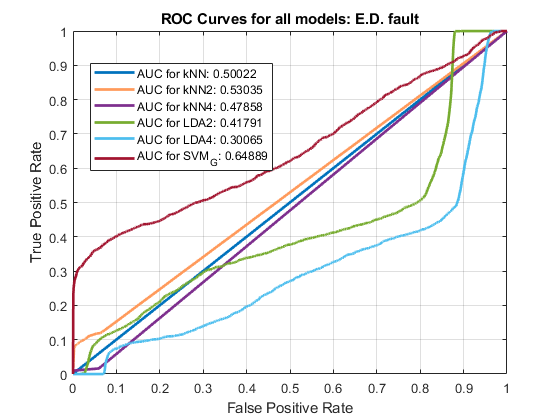

if (plot_ROC_curves_sep)
    % Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
    current = 'S.V.';
    kNN_sep.labels_binary = y_C;
    kNN_sep.labels_binary_num(1:length(kNN_sep.labels_binary)) = 0;
    kNN_sep.labels_binary_num(strcmpi(kNN_sep.labels_binary,current)) = 1;
    kNN_sep.labels_binary_num(kNN_sep.labels_binary_num ~= 1) = 0;
    kNN_sep.labels_binary_num = kNN_sep.labels_binary_num';
    
    kNN_sep.sum_scores = sum(kNN_sep.scores(:, [1, 3:end]), 2);
    
    % Calculate the ROC curve and AUC for kNN
    [kNN_sep.X_roc, kNN_sep.Y_roc, ~, kNN_sep.AUC] = perfcurve(kNN_sep.labels_binary_num, kNN_sep.scores(:, 5), 1);
    
    kNN2_sep.labels_binary = y_C;
    kNN2_sep.labels_binary_num(1:length(kNN2_sep.labels_binary)) = 0;
    kNN2_sep.labels_binary_num(strcmpi(kNN2_sep.labels_binary,current)) = 1;
    kNN2_sep.labels_binary_num(kNN2_sep.labels_binary_num ~= 1) = 0;
    kNN2_sep.labels_binary_num = kNN2_sep.labels_binary_num';
    
    kNN2_sep.sum_scores = sum(kNN2_sep.scores(:, [1, 3:end]), 2);
    
    % Calculate the ROC curve and AUC for kNN2 
    [kNN2_sep.X_roc, kNN2_sep.Y_roc, ~, kNN2_sep.AUC] = perfcurve(kNN2_sep.labels_binary_num, kNN2_sep.scores(:, 5), 1);
    
    kNN4_sep.labels_binary = y_C;
    kNN4_sep.labels_binary_num(1:length(kNN4_sep.labels_binary)) = 0;
    kNN4_sep.labels_binary_num(strcmpi(kNN4_sep.labels_binary,current)) = 1;
    kNN4_sep.labels_binary_num(kNN4_sep.labels_binary_num ~= 1) = 0;
    kNN4_sep.labels_binary_num = kNN4_sep.labels_binary_num';
    
    kNN4_sep.sum_scores = sum(kNN4_sep.scores(:, [1, 3:end]), 2);
    
    % Calculate the ROC curve and AUC for kNN4 
    [kNN4_sep.X_roc, kNN4_sep.Y_roc, ~, kNN4_sep.AUC] = perfcurve(kNN4_sep.labels_binary_num, kNN4_sep.scores(:, 5), 1);
    
   
    LDA2_sep.labels_binary = y_C;
    LDA2_sep.labels_binary_num(1:length(LDA2_sep.labels_binary)) = 0;
    LDA2_sep.labels_binary_num(strcmpi(LDA2_sep.labels_binary,current)) = 1;
    LDA2_sep.labels_binary_num(LDA2_sep.labels_binary_num ~= 1) = 0;
    LDA2_sep.labels_binary_num = LDA2_sep.labels_binary_num';
    
    LDA2_sep.sum_scores = sum(LDA2_sep.scores(:, [1, 3:end]), 2);
    
    % Calculate the ROC curve and AUC for LDA2 
    [LDA2_sep.X_roc, LDA2_sep.Y_roc, ~, LDA2_sep.AUC] = perfcurve(LDA2_sep.labels_binary_num, LDA2_sep.scores(:, 5), 1);
    
    LDA4_sep.labels_binary = y_C;
    LDA4_sep.labels_binary_num(1:length(LDA4_sep.labels_binary)) = 0;
    LDA4_sep.labels_binary_num(strcmpi(LDA4_sep.labels_binary,current)) = 1;
    LDA4_sep.labels_binary_num(LDA4_sep.labels_binary_num ~= 1) = 0;
    LDA4_sep.labels_binary_num = LDA4_sep.labels_binary_num';
    
    LDA4_sep.sum_scores = sum(LDA4_sep.scores(:, [1, 3:end]), 2);
    
    % Calculate the ROC curve and AUC for LDA4 
    [LDA4_sep.X_roc, LDA4_sep.Y_roc, ~, LDA4_sep.AUC] = perfcurve(LDA4_sep.labels_binary_num, LDA4_sep.scores(:, 5), 1);
    
    SVM_G_sep.labels_binary = y_C;
    SVM_G_sep.labels_binary_num(1:length(SVM_G_sep.labels_binary)) = 0;
    SVM_G_sep.labels_binary_num(strcmpi(SVM_G_sep.labels_binary,current)) = 1;
    SVM_G_sep.labels_binary_num(SVM_G_sep.labels_binary_num ~= 1) = 0;
    SVM_G_sep.labels_binary_num = SVM_G_sep.labels_binary_num';
    
    SVM_G_sep.sum_scores = sum(SVM_G_sep.scores(:, [1, 3:end]), 2);
    
    % Calculate the ROC curve and AUC for SVM_G 
    [SVM_G_sep.X_roc, SVM_G_sep.Y_roc, ~, SVM_G_sep.AUC] = perfcurve(SVM_G_sep.labels_binary_num, SVM_G_sep.scores(:, 5), 1);
    
    blue = '#0072BD';
    % Plot the ROC curves
    figure;
    plot(kNN_sep.X_roc, kNN_sep.Y_roc, '-', 'LineWidth', 2, 'Color', blue);
    hold on;
    plot(kNN2_sep.X_roc, kNN2_sep.Y_roc, '-', 'LineWidth', 2, 'Color', orange);
    plot(kNN4_sep.X_roc, kNN4_sep.Y_roc, '-', 'LineWidth', 2, 'Color', purple);
    plot(LDA2_sep.X_roc, LDA2_sep.Y_roc, '-', 'LineWidth', 2, 'Color', green);
    plot(LDA4_sep.X_roc, LDA4_sep.Y_roc, '-', 'LineWidth', 2, 'Color', cyan);
    plot(SVM_G_sep.X_roc, SVM_G_sep.Y_roc, '-', 'LineWidth', 2, 'Color', maroon);
    xlabel('False Positive Rate');
    ylabel('True Positive Rate');
    title('ROC Curves for all models: E.D. fault');
    legend(['AUC for kNN: ', num2str(kNN_sep.AUC)],['AUC for kNN2: ', num2str(kNN2_sep.AUC)],['AUC for kNN4: ', num2str(kNN4_sep.AUC)],['AUC for LDA2: ', num2str(LDA2_sep.AUC)],['AUC for LDA4: ', num2str(LDA4_sep.AUC)],['AUC for SVM_G: ', num2str(SVM_G_sep.AUC)], 'Location', 'Best');
    grid on;
    hold off;
    print('results/Performance/testing_half/ROC_Fault4', '-dpng', '-r600')
end

kNN_sep.c = confusionmat(y_C, kNN_sep.y_pred);
disp(kNN_sep.c)

      838140       31852          67          47           0
      238391       17858           0           0           0
        1920           1           0           0           0
      157196        7814           0           0           0
        2719           0           0           0           0



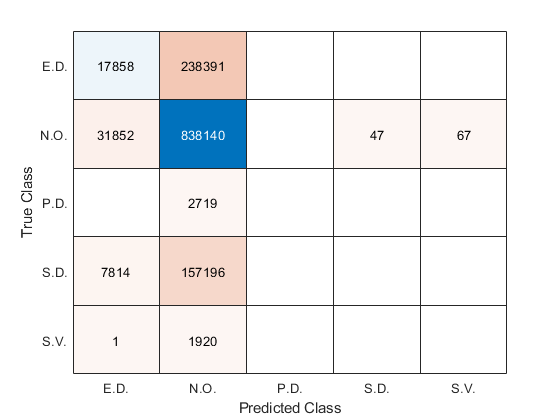

confusionchart(y_C, kNN_sep.y_pred);

kNN_sep.accuracy = sum(strcmpi(kNN_sep.y_pred, y_C)) / length(y_C);
kNN2_sep.accuracy = sum(strcmpi(kNN2_sep.y_pred, y_C)) / length(y_C);
kNN4_sep.accuracy = sum(strcmpi(kNN4_sep.y_pred, y_C)) / length(y_C);
LDA2_sep.accuracy = sum(strcmpi(LDA2_sep.y_pred, y_C)) / length(y_C);
LDA4_sep.accuracy = sum(strcmpi(LDA4_sep.y_pred, y_C)) / length(y_C);
SVM_G_sep.accuracy = sum(strcmpi(SVM_G_sep.y_pred, y_C)) / length(y_C);
sep_accuracies = [kNN_sep.accuracy; kNN2_sep.accuracy; kNN4_sep.accuracy; LDA2_sep.accuracy; LDA4_sep.accuracy; SVM_G_sep.accuracy];


full_accuracies = [M_kNN; M_kNN2; M_kNN4; M_LDA2; M_LDA4; M_SVM_G];

### Save performance data

if (save_performance)
combined_accuracies = table();
combined_accuracies.sep_acc = sep_accuracies;
combined_accuracies.full_acc = full_accuracies;
writetable(combined_accuracies, "results/Performance/testing/accuracies.csv");

kNN.performance = table();
kNN.performance.precision = kNN.precision;
kNN.performance.sensitivity = kNN.sensitivity;
kNN.performance.specificity = kNN.specificity;
writetable(kNN.performance, "results/Performance/testing/kNN_performance.csv");

kNN2.performance = table();
kNN2.performance.precision = kNN2.precision;
kNN2.performance.sensitivity = kNN2.sensitivity;
kNN2.performance.specificity = kNN2.specificity;
writetable(kNN2.performance, "results/Performance/testing/kNN2_performance.csv");

kNN4.performance = table();
kNN4.performance.precision = kNN4.precision;
kNN4.performance.sensitivity = kNN4.sensitivity;
kNN4.performance.specificity = kNN4.specificity;
writetable(kNN4.performance, "results/Performance/testing/kNN4_performance.csv");

LDA2.performance = table();
LDA2.performance.precision = LDA2.precision;
LDA2.performance.sensitivity = LDA2.sensitivity;
LDA2.performance.specificity = LDA2.specificity;
writetable(LDA2.performance, "results/Performance/testing/LDA2_performance.csv");

LDA4.performance = table();
LDA4.performance.precision = LDA4.precision;
LDA4.performance.sensitivity = LDA4.sensitivity;
LDA4.performance.specificity = LDA4.specificity;
writetable(LDA4.performance, "results/Performance/testing/LDA4_performance.csv");

SVM_G.performance = table();
SVM_G.performance.precision = SVM_G.precision;
SVM_G.performance.sensitivity = SVM_G.sensitivity;
SVM_G.performance.specificity = SVM_G.specificity;
writetable(SVM_G.performance, "results/Performance/testing/SVM_G_performance.csv");
end